clear all; close all; clc;

% SET IMPORTANT VARIABLES
datafolder = '../data/delay_match_to_sample/';
filtername = 'DNMS_gonogo_Data.mat';
odor_duration = 0.75; % in seconds
start_tone_duration = 0.25; % in seconds

% LOAD DATA from .mat file

% find all .mat files in datafolder and ask user to select one
files = dir(fullfile(datafolder,'*.mat'));
filenames = {files.name};

% keep only files that contain filtername
idx = contains(filenames,filtername);
filenames = filenames(idx);

% sort filenames
[~,idx] = sort(filenames);
filenames = filenames(idx);

% ask user to select one file
[idx,~] = listdlg('PromptString','Select a file:','SelectionMode','single','ListString',filenames);
filename = filenames{idx};
% delete temporary variables
clear files filenames idx filtername

% load data
load([datafolder filename]);

% get the M field in the exper struct
DATA = exper.M;

% extract the fields of interest (columns of DATA; dont keeo last timestep
% 1: time
% 11: trial number
% 3: start tone
% 4,5: odor 1,2
% 9: water delivered
% 15: lick contact

time = DATA(1:end-1,1);
trial = DATA(1:end-1,11);
start_tone = DATA(1:end-1,3);
odor1 = DATA(1:end-1,4);
odor2 = DATA(1:end-1,5);
water = DATA(1:end-1,9);
lick = DATA(1:end-1,15);

% delete temporary variables
clear exper DATA;

% get the unique trial numbers and sort them
trial_numbers = unique(trial);
trial_numbers = sort(trial_numbers);
max_trial_number = max(trial_numbers);

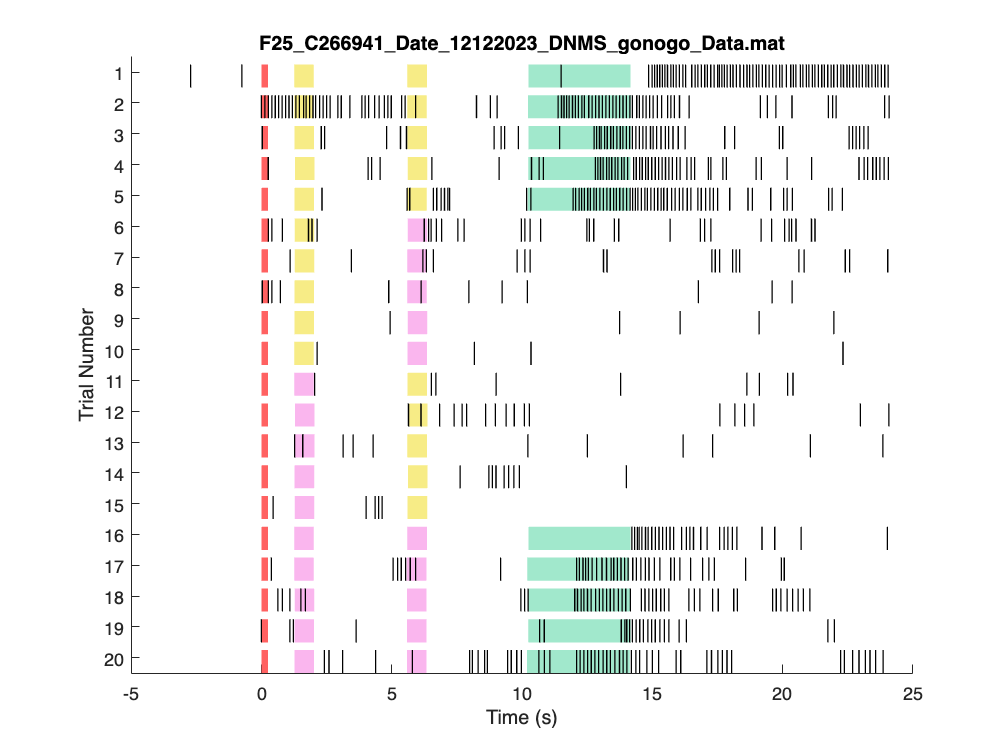

figure;
% loop through each trial number and extract the data for that trial
for i = 1:length(trial_numbers)
    % trial number sets the y-axis value
    y = max_trial_number - trial_numbers(i);
    
    % get the index where the trial number is equal to the current trial number
    idx = trial == trial_numbers(i);

    % get the time for the current trial and reorigin it
    time_trial = time(idx);

    % get the time of the start tone for the current trial
    start_tone_trial = start_tone(idx);
    start_tone_time = time_trial(start_tone_trial == 1);

    % reorigin the trial to the start tone
    time_trial = time_trial - start_tone_time(1);
    start_tone_time = start_tone_time - start_tone_time(1);
    
    % plot the start tone (rectangle at [start_tone_time, y] with width start_tone_duration and height 1)
    rectangle('Position',[start_tone_time,y,start_tone_duration,0.75],'FaceColor','#ff6161','EdgeColor','none');

    % get the time of the odor1 (local time)
    odor1_trial = odor1(idx);
    odor1_time = time_trial(odor1_trial == 1);
    
    % loop through each odor1 time and plot a rectangle at [odor1_time, y] with width odor_duration and height 1
    for j = 1:length(odor1_time)
        rectangle('Position',[odor1_time(j),y,odor_duration,0.75],'FaceColor','#f7ec86','EdgeColor','none');
    end

    % get the time of the odor2 (local time)
    odor2_trial = odor2(idx);
    odor2_time = time_trial(odor2_trial == 1);

    % loop through each odor2 time and plot a rectangle at [odor2_time, y] with width odor_duration and height 1
    for j = 1:length(odor2_time)
        rectangle('Position',[odor2_time(j),y,odor_duration,0.75],'FaceColor','#fab6ee','EdgeColor','none');
    end

    % get the time of the water (local time)
    water_trial = water(idx);
    water_time = time_trial(water_trial == 1);
    % check if water was delivered
    if ~isempty(water_time)
        water_time_onset = water_time(1);
        water_time_offset = water_time(end);
        % plot a rectangle at [water_time_onset, y] with width water_time_offset - water_time_onset and height 1
        rectangle('Position',[water_time_onset,y,water_time_offset - water_time_onset,0.75],'FaceColor','#a1e8cc','EdgeColor','none');
    end

    % get the times of the licks (local time)
    lick_trial = lick(idx);
    delta_lick_trial = diff(lick_trial)>2;
    lick_times = time_trial(1:end-1);
    lick_times = lick_times(delta_lick_trial);

    % loop through each lick time and plot a rectangle at [lick_time, y] with width 0.05 and height 1
    for j = 1:length(lick_times)
        rectangle('Position',[lick_times(j),y,0.05,0.75],'FaceColor','black','EdgeColor','none');
    end

    % clear temporary variables
    clear idx time_trial start_tone_trial odor1_trial odor2_trial water_trial lick_trial delta_lick_trial;

    % end of trial loop
end

% set the y-axis labels
yticks(0.5:max_trial_number-0.5);
yticklabels(flip(trial_numbers));
xlabel('Time (s)');
ylabel('Trial Number');
title(filename,"Interpreter","none");